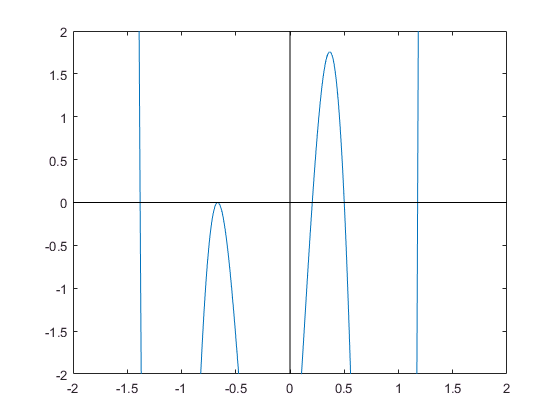

clc;
clear;
close all;
syms x;

f(x) = 54 * x.^6 + 45 * x.^5 - 102 * x.^4 - 69 * x.^3 + 35 * x.^2 + 16 * x - 4;

fplot(f, [-2, 2])
ylim([-2. 2])
line(xlim, [0,0], 'Color', 'k')
line([0,0], ylim, 'Color', 'k')

% Finding exact solutions
exact_sols = vpasolve(f == 0, x);
uniq_exact_sols = vpa(unique(exact_sols), 7)

$$uniq\_exact\_sols = \left(\begin{array}{c} -1.381298\\ -0.6666667\\ 0.2051829\\ 0.5\\ 1.176116 \end{array}\right)$$

total_unique_sols = length(uniq_exact_sols);

tol = 10^-5;
initial_guesses = [-1.5 -1.3; -0.6 0.25; 0.1 0.3; 0.4 0.6; 1.1 1.3];

% For each unique roots
for n = 1:total_unique_sols
    
    results(1, 1:4) = [0 0 0 0];
    % Initial guesses
    a = initial_guesses(n, 1);
    b = initial_guesses(n, 2);
    
    if f(a) * f(b) > 0
        disp(' ')
        disp(' ')
        fprintf('Try changing initial guess for root no %d', n)
        vpa(f(a))
        vpa(f(b))
        continue;
    end
    
    % Iteration for one root between a and b with 30 limit
    for i = 1:30
        
        p = b - (f(b) * (b - a))/(f(b) - f(a));
        results(i, 1:4) = [i a b p];
        
        if n == 2
           fprintf('%d %f', i, p)  
        end
        
        if (abs(p - b)) < tol
           break;
        else
            a = b; b = p;
        end
    end
    
    Iteration_Number = results(1:i, 1);
    An = results(1:i,2);
    Bn = results(1:i,3);
    Xn = results(1:i,4);
    Abs_Error = double(abs(results(1:i, 4) - uniq_exact_sols(n)));
    
    disp(' ')
    disp(' ')
    fprintf('%dth root', n)
    fprintf('Exact solution: %f', uniq_exact_sols(n))
    fprintf('Appproximate solution: %f', results(i, 4))
    table(Iteration_Number, An, Bn, Xn, Abs_Error)
end

1th root

Exact solution: -1.381298

Appproximate solution: -1.381302

ans =     Iteration_Number      An         Bn         Xn       Abs_Error 
    ________________    _______    _______    _______    __________

    1                      -1.5       -1.3    -1.3451      0.036242
    2                      -1.3    -1.3451    -1.4001      0.018782
    3                   -1.3451    -1.4001    -1.3782     0.0030954
    4                   -1.4001    -1.3782    -1.3811    0.00024247
    5                   -1.3782    -1.3811    -1.3813    3.2959e-06


1 -0.364140

2 0.146950

3 0.369595

4 0.235341

5 0.176761

6 0.206488

7 0.205230

2 3

2 4

2 5

2 6

2 7

4th root

Exact solution: 0.500000

Appproximate solution: 0.499998

ans =     Iteration_Number      An         Bn         Xn       Abs_Error 
    ________________    _______    _______    _______    __________

    1                       0.4        0.6    0.45953      0.040469
    2                       0.6    0.45953    0.48655      0.013449
    3                   0.45953    0.48655    0.50286     0.0028596
    4                   0.48655    0.50286    0.49983    0.00016684
    5                   0.50286    0.49983        0.5    1.9633e-06


5th root

Exact solution: 1.176116

Appproximate solution: 1.176115

ans =     Iteration_Number      An        Bn        Xn      Abs_Error 
    ________________    ______    ______    ______    __________

    1                      1.1       1.3    1.1439      0.032213
    2                      1.3    1.1439    1.1635      0.012655
    3                   1.1439    1.1635    1.1779     0.0018285
    4                   1.1635    1.1779     1.176    9.4757e-05
    5                   1.1779     1.176    1.1761    6.8755e-07
